## Step 1: Load and prepare data. 

The data must be normalized for use in a CNN prediction model.

%addpath(genpath('MATLAB-Drive'))
try
    gd = gpuDevice;
    exEn = 'gpu';
catch ME
    warning("GPU not found!");
    exEn = 'cpu';
end
load dataset_CuttingTools.mat

% normalize the regression outputs
ytrain_min = min(dataTrain.ylabel(:));
ytrain_max = max(dataTrain.ylabel(:));
ytrain = normalize(dataTrain.ylabel(:),'range',[0,1]);

yval_min = min(dataValidation.ylabel(:));
yval_max = max(dataValidation.ylabel(:));
yval = normalize(dataValidation.ylabel(:),'range',[0,1]);

xtrain_norm = zeros(size(predictorsTrain.Var1));
xtest_norm = zeros(size(predictorsTest.Var1));
xval_norm = zeros(size(predictorsValidation.Var1));

% normalize each predictor between 0 and 1
for i = 1:width(predictorsTrain.Var1)
    xtrain_min(i) = min(table2array(predictorsTrain.Var1(:,i)));
    xtrain_max(i) = max(table2array(predictorsTrain.Var1(:,i)));
    xtrain_norm(:,i) = normalize(table2array(predictorsTrain.Var1(:,i),'range',[0,1]));
    
    xtest_min(i) = min(table2array(predictorsTest.Var1(:,i)));
    xtest_max(i) = max(table2array(predictorsTest.Var1(:,i)));
    xtest_norm(:,i) = normalize(table2array(predictorsTest.Var1(:,i),'range',[0,1]));
    
    xval_min(i) = min(table2array(predictorsValidation.Var1(:,i)));
    xval_max(i) = max(table2array(predictorsValidation.Var1(:,i)));
    xval_norm(:,i) = normalize(table2array(predictorsValidation.Var1(:,i),'range',[0,1]));
end

imdsTrain = dataTrain(:,:);
imdsValidation = dataValidation(:,:);

figure(1); 
subplot(1,3,1)

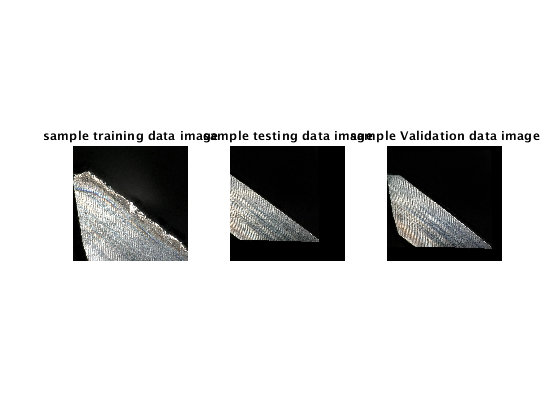

imshow(imread(dataTrain.filename(1)));
title('sample training data image');
subplot(1,3,2)
imshow(imread(dataTest.filename(1)));
title('sample testing data image');
subplot(1,3,3)
imshow(imread(dataValidation.filename(1)));
title('sample Validation data image');

## Step 2: Load and prepare models to use in CNN prediction

models = ["alexnet", "resnet18", "resnet50", "resnet101", "inceptionv3","squeezenet"];


for i = 1:numel(models)
    [tmpNet, TmpExpNames] = loadPretrainedCNN(models(i),0,"");
    
    expNames{i} = TmpExpNames;
    inputSize{i} = tmpNet.Layers(1).InputSize;
    
    regLayer = weightedCompoundLossLayer(2,'regout_NMKMMD_NMSE');
    tmpNet = removeLayers(tmpNet,tmpNet.Layers(end).Name);
    tmpNet = addLayers(tmpNet,regLayer); 
    learnRate = 50;
    rl = regLayer.Name;
    %regLayer = setLearnRateFactor(regLayer(1),learnRate);
    %fprintf('Learn rate factor of %d set for final Regression Layer %s',learnRate,rl)
    sl = tmpNet.Layers(end-1).Name;
    tmpNet = connectLayers(tmpNet,sl,rl);
    fprintf('Layer %s successfully replaced with %s \n', sl, rl);
    %tmpNet(end) = setLearnRateFactor(tmpNet(end),'Weights',50);
    %analyzeNetwork(tmpNet)
    nets{i} = tmpNet;
end

'LossName' Argument passed to Assert function: 
 LossName: mse
 LossVal: 0 
mse 
Model selected: alexnet with 0 class outputs (0 == regression) 
Loss function: mse 
Indexes of First FC layer: 17 
Indexes of Second FC layer: 20 
Indexes of Last FC layer: 23 


layersBefore =   25x1 Layer array with layers:

     1   'data'     Image Input                   227x227x3 images with 'zerocenter' normalization
     2   'conv1'    Convolution                   96 11x11x3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'    ReLU                          ReLU
     4   'norm1'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'    Grouped Convolution           2 groups of 128 5x5x48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'    ReLU                          ReLU
     8   'norm2'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'    Max Pooling                   3x3 max pooling with stride [2  2] and padding

layersBefore =   25x1 Layer array with layers:

     1   'data'     Image Input                   227x227x3 images with 'zerocenter' normalization
     2   'conv1'    Convolution                   96 11x11x3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'    ReLU                          ReLU
     4   'norm1'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'    Grouped Convolution           2 groups of 128 5x5x48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'    ReLU                          ReLU
     8   'norm2'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'    Max Pooling                   3x3 max pooling with stride [2  2] and padding

Weights Initializer for fully connected layers fc7 and fc8 set to zeros. 
Creating layer graph....


Layer fcfinal successfully replaced with regout_NMKMMD_NMSE 


'LossName' Argument passed to Assert function: 
 LossName: mse
 LossVal: 0 
mse 
Model selected: resnet18 with 0 class outputs (0 == regression) 
Loss function: mse 
Weights Initializer for fully connected layer 69 set to zeros. 
Creating layer graph....


Layer fcfinal successfully replaced with regout_NMKMMD_NMSE 


'LossName' Argument passed to Assert function: 
 LossName: mse
 LossVal: 0 
mse 
Model selected: resnet50 with 0 class outputs (0 == regression) 
Loss function: mse 
Weights Initializer for fully connected layer 175 set to zeros. 
Creating layer graph....


Layer fcfinal successfully replaced with regout_NMKMMD_NMSE 


'LossName' Argument passed to Assert function: 
 LossName: mse
 LossVal: 0 
mse 
Model selected: resnet101 with 0 class outputs (0 == regression) 
Loss function: mse 
Weights Initializer for fully connected layer 345 set to zeros. 
Creating layer graph....


Layer fcfinal successfully replaced with regout_NMKMMD_NMSE 


'LossName' Argument passed to Assert function: 
 LossName: mse
 LossVal: 0 
mse 
Model selected: inceptionv3 with 0 class outputs (0 == regression) 
Loss function: mse 
Weights Initializer for fully connected layer 313 set to zeros. 
Creating layer graph....


Layer fcfinal successfully replaced with regout_NMKMMD_NMSE 


'LossName' Argument passed to Assert function: 
 LossName: mse
 LossVal: 0 
mse 
Model selected: squeezenet with 0 class outputs (0 == regression) 
Loss function: mse 


Layer fcfinal successfully replaced with regout_NMKMMD_NMSE 


   
pixelRange = [-30 30];
%rotRange = [-15 15];
scaleRange = [0.8 1.2];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange,...
    'RandRotation',pixelRange/2);


## Step 3: Run model training, then predict using the model.

for i = 1:numel(models)
    
    augimdsTrain = augmentedImageDatastore(inputSize{i}(1:2),imdsTrain(:,1:2), ...
        'DataAugmentation',imageAugmenter);
    augimdsValidation = augmentedImageDatastore(inputSize{i}(1:2),imdsValidation(:,1:2));

    options = trainingOptions('adam', ...
        'MiniBatchSize',8, ...
        'MaxEpochs',50, ...
        'LearnRateSchedule','piecewise',...
        'LearnRateDropPeriod',10,...
        'LearnRateDropFactor',0.9,...
        'InitialLearnRate',2e-4, ...
        'Shuffle','every-epoch', ...
        'ValidationData',augimdsValidation, ...
        'ValidationFrequency',10, ...
        'ValidationPatience',Inf, ...
        'Verbose',true, ...
        'Plots','training-progress',...
        'ExecutionEnvironment','cpu');
    for j = 1:5
    if exEn == 'gpu'
    reset(gd);
    end
    tic;
    [net, info] = trainNetwork(augimdsTrain,nets{i},options);
    tt = toc;
    % predict outputs directly here
    YPred{i} = predict(net,augimdsValidation,'MiniBatchSize',16);
    
    YActual{i} = imdsValidation.ylabel;
        
    predictionError = abs(YActual{i} - YPred{i});
    MAE = mean(predictionError)
    squares = predictionError.^2;
    rmse = sqrt(mean(squares))
    
    thr_10 = 0.10;
    thr_20 = 0.20;
    thr_30 = 0.30;
    numCorrect_10 = sum(predictionError < thr_10);
    numCorrect_20 = sum(predictionError < thr_20);
    numCorrect_30 = sum(predictionError < thr_30);
    
    numValidationImages = numel(imdsValidation.ylabel);
    
    accuracy_10 = numCorrect_10/numValidationImages
    accuracy_20 = numCorrect_20/numValidationImages
    accuracy_30 = numCorrect_30/numValidationImages
    % compute j runs of each training loop and store in val_accuracy
    val_accuracy{j} = [accuracy_10,accuracy_20,accuracy_30]
    training_time(j) = tt;
    
    % calculate the activations of extracted CNN features on the training
    % data at specified layer indexes
    tf = findCNNFCLayers(net);
    lyrs = net.Layers(tf);
    ef1_train = activations(net,augimdsTrain,lyrs(end-2).Name,'OutputAs','rows');
    ef2_train = activations(net,augimdsTrain,lyrs(end-1).Name,'OutputAs','rows');
    
    end
    % model validation accuracy is j-run average of each model
  model_acc = reshape(cell2mat(val_accuracy),[3,j])';
  val_acc_10_avg(i) = mean(model_acc(:,1));
  val_acc_20_avg(i) = mean(model_acc(:,2));  
  val_acc_30_avg(i) = mean(model_acc(:,3));
  trainingTime_avg(i) = mean(training_time(1:j));
  
  modelPerformance{i} = struct('ModelName',expNames{i}, ...
      'ValidationAccuracy', ...
      [val_acc_10_avg(i),val_acc_20_avg(i),val_acc_30_avg(i)],...
      'TrainingTime',trainingTime_avg(i), ...
      'Predictions',YPred{i});
    %% visualize an image feature which strongly activates the trained model's
  % feature extractor layers
  %fc_ds_2 = 'fc_downsampling_2';
  fc_ds_3 = 'fc_downsampling_3';

  %I1_fc_downsampled2 = deepDreamImage(net,fc_ds_2,1:410);
  
if~strcmp(models(i),"squeezenet")
  I1 = deepDreamImage(net,fc_ds_3,1:72);
end
  
  figs = findall(groot,'Type','Figure');
  % set figures to be all the figures but 1
  figs = figs(2:end);
  close(figs)
  clc;
  
  % visualize a selection of the image features 1:72
  if ~strcmp(models(i),"squeezenet")
  figure(i); clf res+et;
  montage(I1(:,:,:,1:72));
  title(sprintf("Visualized features for final feature extraction layer of %s",expNames{i}));
  featureBank_im = expNames{i}+".png"
  saveas(gcf,featureBank_im)
  end
  fprintf("Model name: %s acc_10 = %2.2f % \n ____________________________ \n",expNames{i},val_acc_10_avg(i))
  
  
end



## Step 4: Evaluate prediction performance and test on test set.